# Signaler och system - Lab 1

### 1. Differentialekvationer, differensekvationer och faltning

1.b)

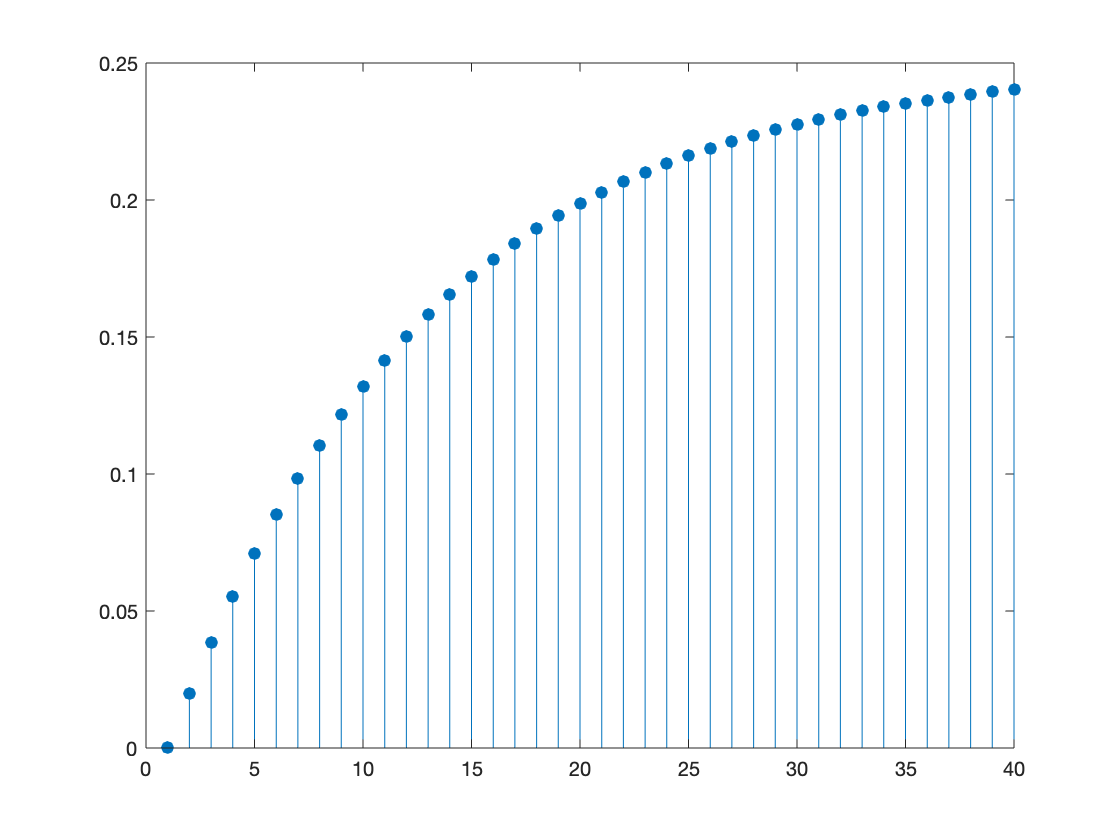

clear all
y = zeros(1,40);
x = ones(1,40);

for n=2:1:40
    y(n) = y(n-1)-0.08*y(n-1)+0.02*x(n-1);
end

stem(y, 'filled');

2.a) och 3.a)

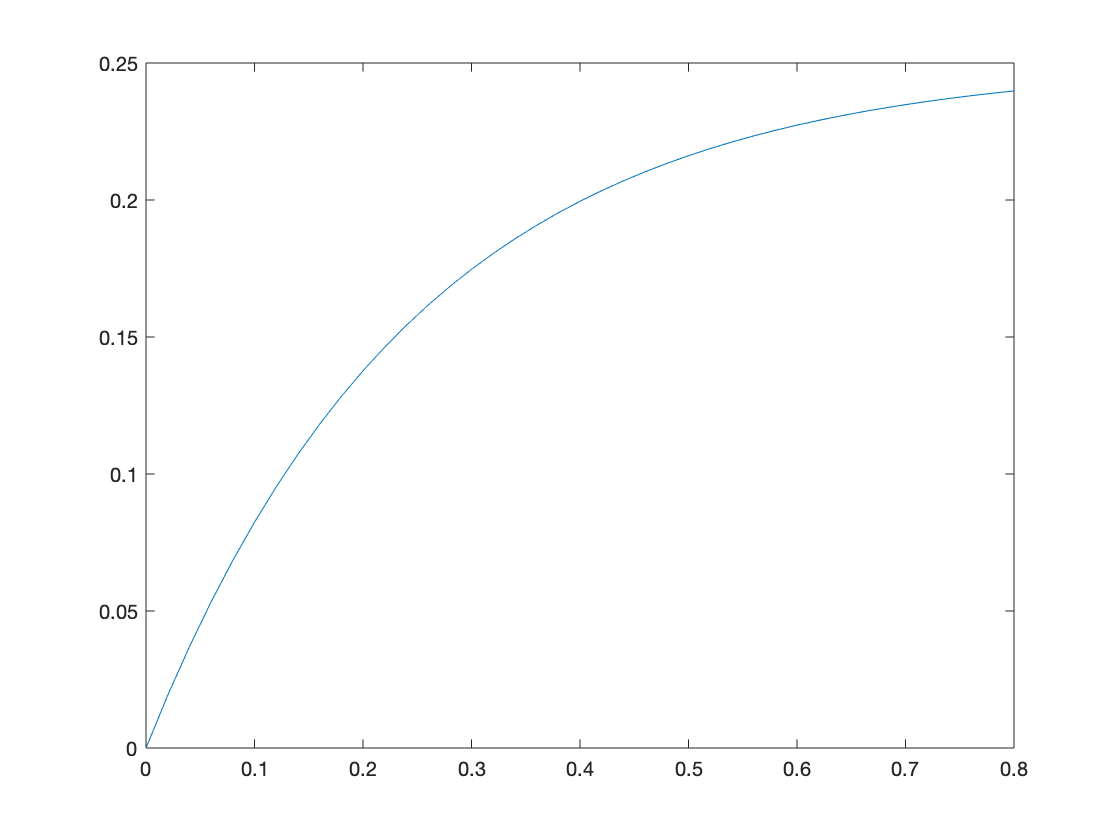

t = 0:0.02:0.8;
y= 1/4 -exp(-4*t)/4; %Intervallet mellan 0 och 0.8. samplingsintervallet är 0.02

figure
plot(t,y)

4

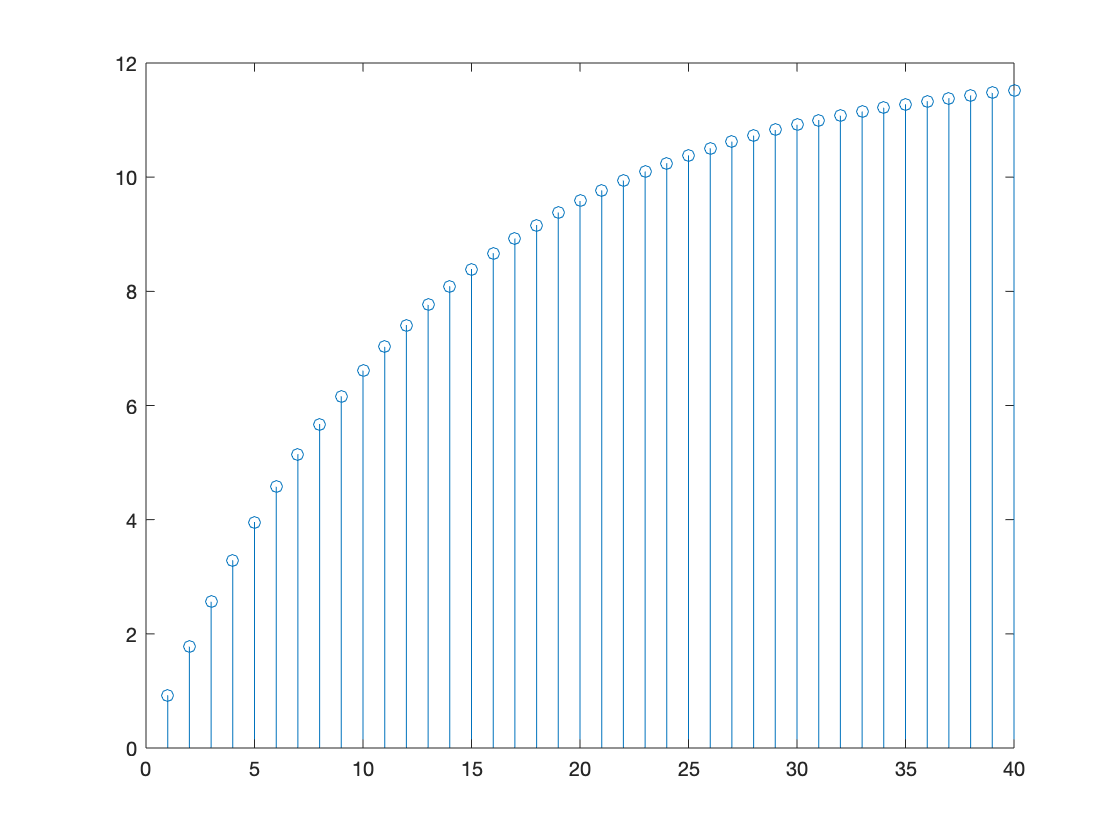

Ts = 0.02; %samplingsintervall

% 4.a)
for n =1:40
h(n) = exp(-4*Ts*n);
end

% 4.b)
x = ones(1,40); %insignalen skulle vara 40sa från en stegsignal
c = conv(h,x); %faltningsoperationen utförs.

% 4.c)
c = c(1:40);

stem(c)

5

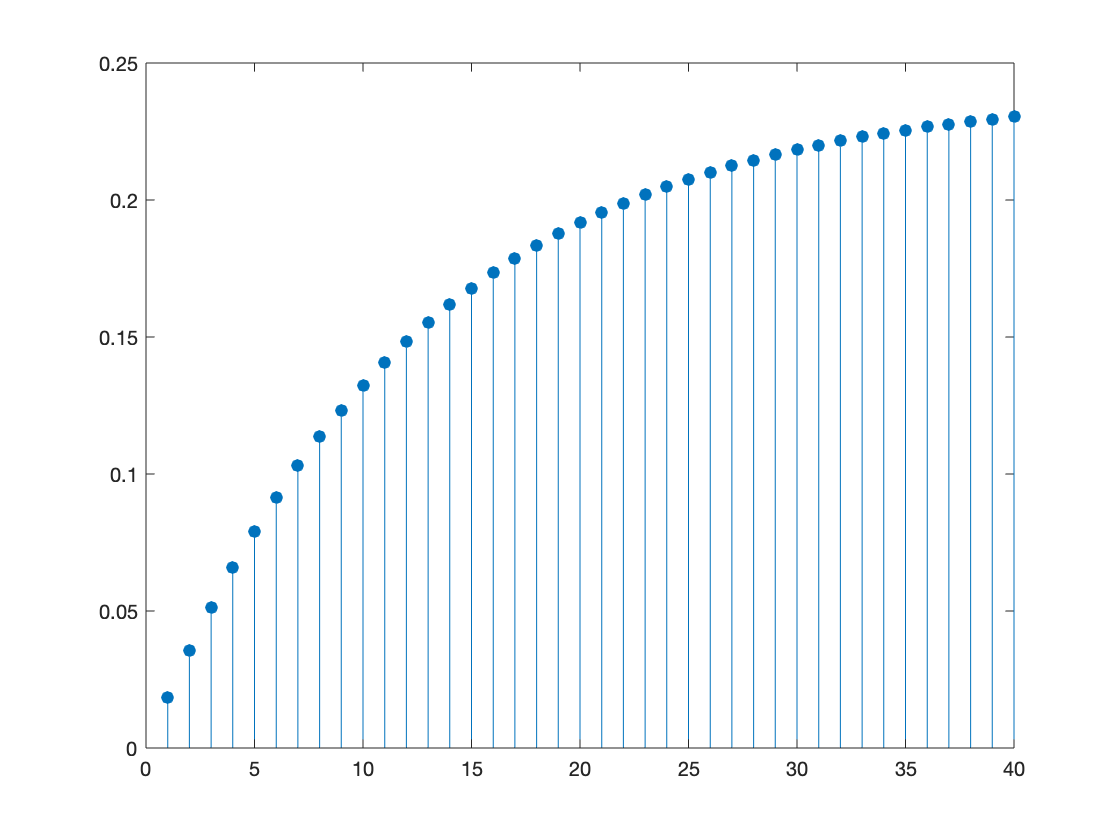

stem(Ts*c, 'filled');

6.

clear all

[y,fs]=audioread('BuzzE1.wav');

Ts = 0.3;
z = Ts*fs;
z = round(z);

nollor = zeros(1,z);%vektor med nollr som ska representera tidsfördröjningen
h = [1, nollor, 1, nollor, 1];%skapar impulssvare
% nollor %antal nollor

c = conv(y,h); %faltning, skapar ett eko.
%soundsc(c,fs);


### 2. TILLÄMPNINGAR MED FREKVENSANALYS

7.

clear all
load 'piano1.mat';

% fs: samplingstakten
% fs = fs*2; %dubbelt så hög samplingstakt 
% fs = fs * 0.5; %hälften så hög samplingstak

%soundsc(y1,fs);

8.

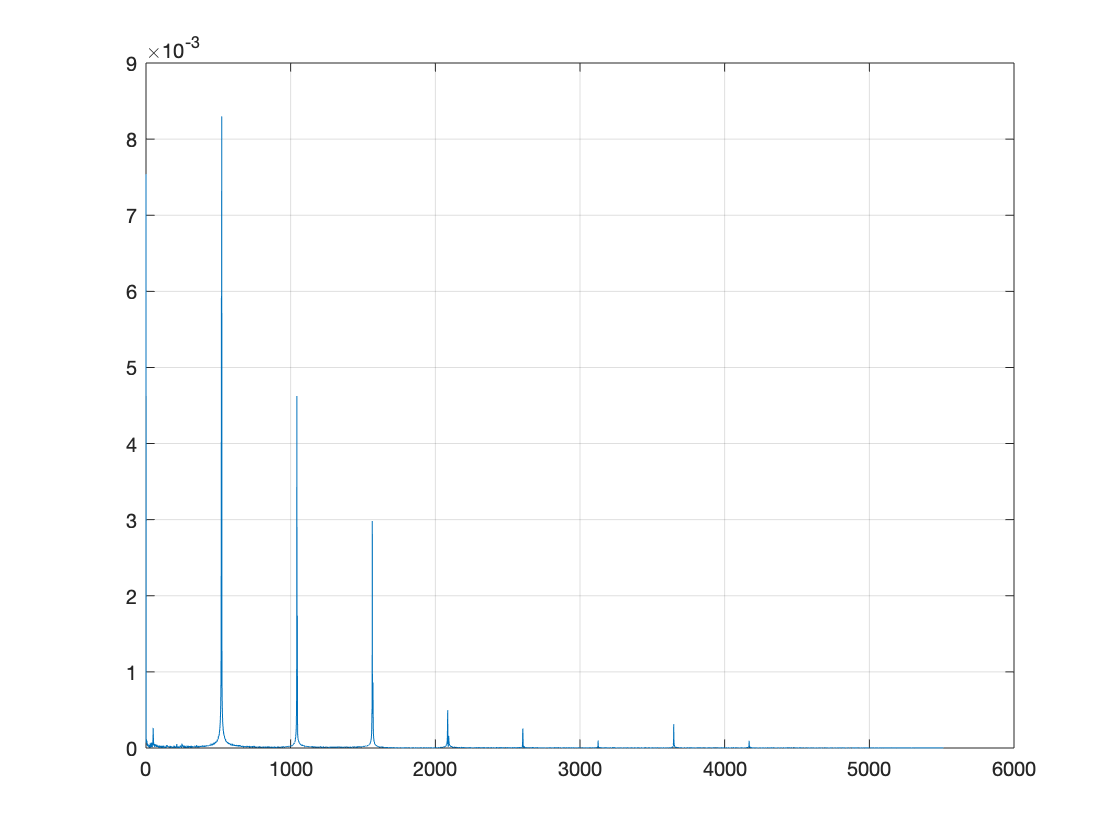

X=fft(y1);
N=length(X);
f=0:fs/N:fs/2;
X_magn=abs(X)/(N/2);
plot(f,X_magn(1:length(f)));
grid;


Y=fft(y1);
length(y1)

ans = 10001

N = length(Y)

N = 10001

fs/N %frekvensfelet

ans = 1.1024

9.

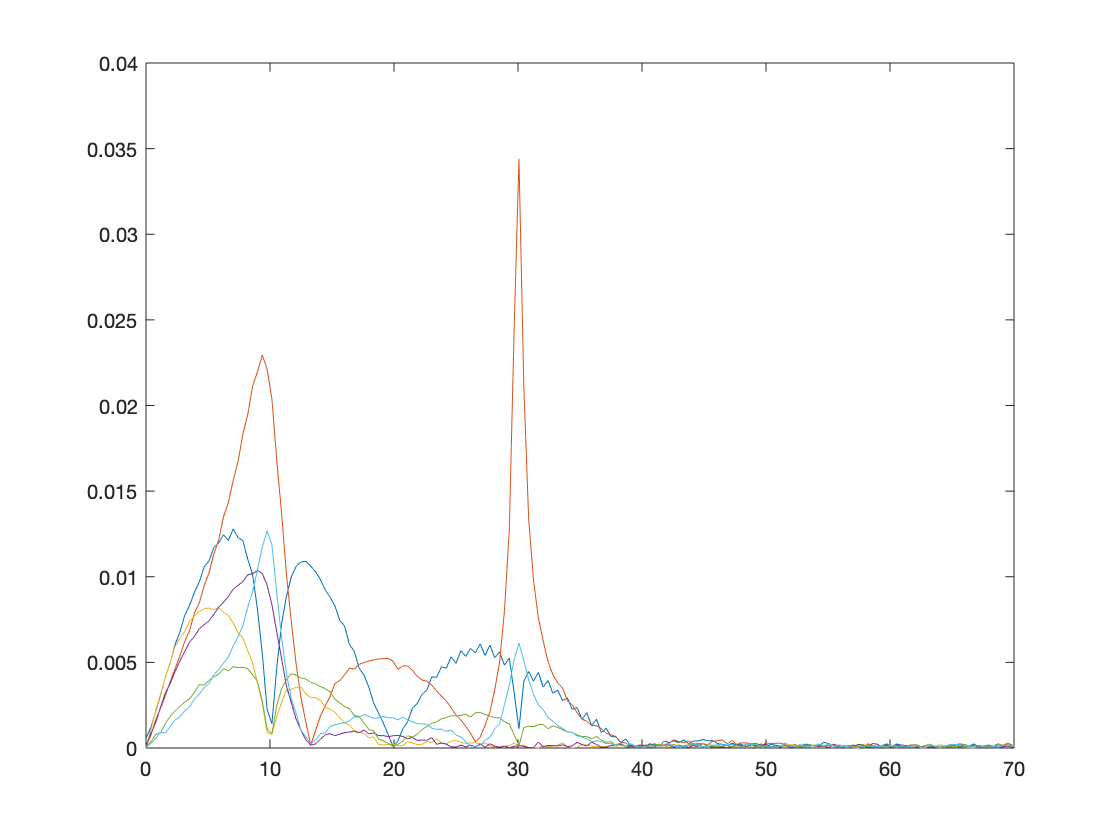

load 'balk.mat'
Y11=abs(fft(y11));
Y12=abs(fft(y12));
Y21=abs(fft(y21));
Y22=abs(fft(y22));
Y31=abs(fft(y31));
Y32=abs(fft(y32));

N = length(Y11); %alla vektorer har samma längd, spelar ingen roll vilken jag tar
f = 0:(fs/N):(fs/2); %frekvensanalys
M = length(f);

figure
plot(f,abs(Y11(1:M))/(M/2))
hold on
plot(f,abs(Y12(1:M))/(M/2)) 
hold on
plot(f,abs(Y21(1:M))/(M/2))
hold on
plot(f,abs(Y22(1:M))/(M/2))
hold on
plot(f,abs(Y31(1:M))/(M/2))
hold on
plot(f,abs(Y32(1:M))/(M/2))
axis([0 70 0 0.04])
hold off

11.

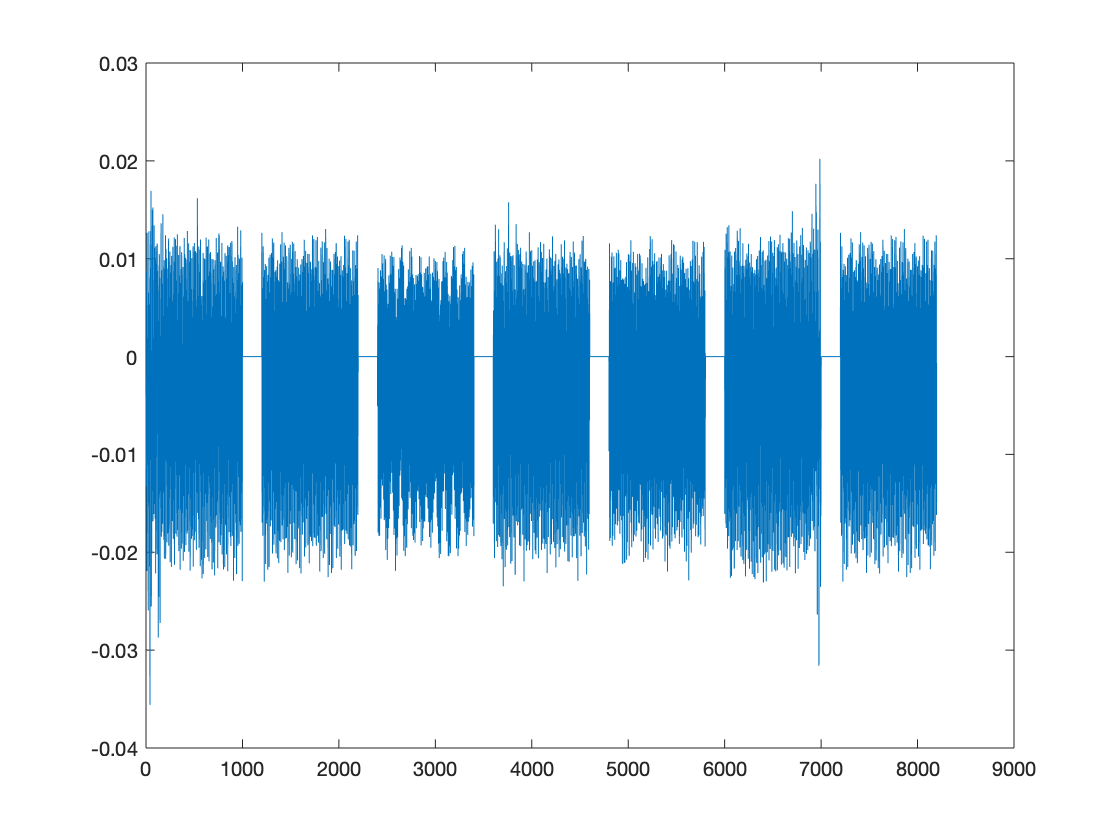

clear all
load 'phonenumber.mat'

y1=y(1:1100);
y2=y(1201:2200);
y3=y(2401:3400);
y4=y(3601:4600);
y5=y(4801:5800);
y6=y(6001:7000);
y7=y(7201:8198);

X=fft(y1); %man måste byta vektor manuellt här för att plotta fram all toner
N=length(X);
f1=0:(fs/N):fs/2;
M1=(length(f1));

plot(y);


figure
plot(f1,abs(X(1:M1))/N);